img1 = imread("stop1.jpg");
img2 = imread("stop2.jpg");

img1gray = im2gray(img1);
img2gray = im2gray(img2);

points1 = detectSURFFeatures(img1gray);

points1 =   771×1 SURFPoints array with properties:

              Scale: [771×1 single]
    SignOfLaplacian: [771×1 int8]
        Orientation: [771×1 single]
           Location: [771×2 single]
             Metric: [771×1 single]
              Count: 771


points2 = detectSURFFeatures(img2gray);

points2 =   757×1 SURFPoints array with properties:

              Scale: [757×1 single]
    SignOfLaplacian: [757×1 int8]
        Orientation: [757×1 single]
           Location: [757×2 single]
             Metric: [757×1 single]
              Count: 757


[features1, validPoints1] = extractFeatures(img1gray, points1);
[features2, validPoints2] = extractFeatures(img2gray, points2);

indexPairs = matchFeatures(features1, features2);

indexPairs(15, :)

ans = 1×2 uint32 row vector
    71   284


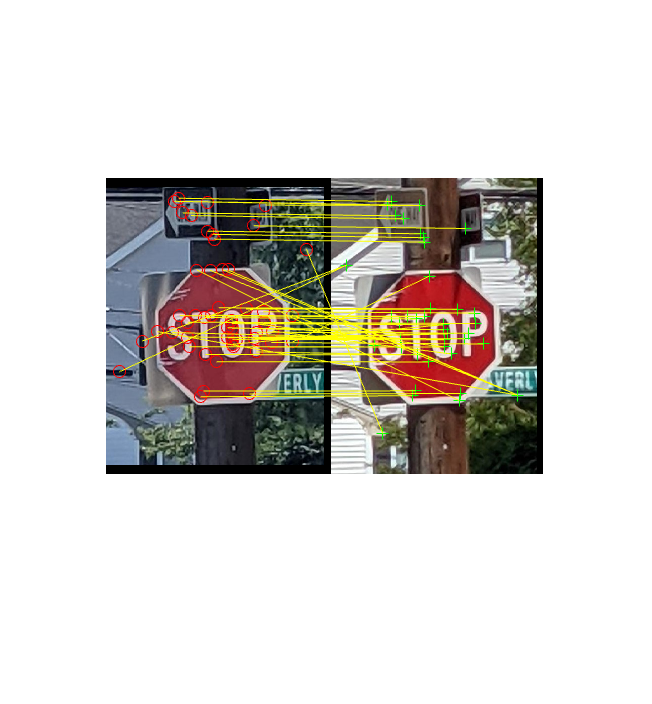

matchedPoints1=validPoints1(indexPairs(:,1),:);
matchedPoints2=validPoints2(indexPairs(:,2),:);

showMatchedFeatures(img1,img2,matchedPoints1,matchedPoints2, "montage");